x0 = 100;
x = lsqnonlin(@(x) myfun(x,0.01),x0) % 使用只有一个参数的匿名函数，调用有多个参数的myfun函数，实现给myfun传递额外参数


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x = 1.2926

t = linspace(0,3);
predicted = exp(-t*x(1))

predicted =     1.0000    0.9616    0.9246    0.8891    0.8550    0.8221    0.7906    0.7602    0.7310    0.7029    0.6759    0.6499    0.6250    0.6010    0.5779    0.5557    0.5343    0.5138    0.4941    0.4751    0.4568    0.4393    0.4224    0.4062    0.3906    0.3756    0.3612    0.3473    0.3339    0.3211    0.3088    0.2969    0.2855    0.2746    0.2640    0.2539    0.2441    0.2347    0.2257    0.2170    0.2087    0.2007    0.1930    0.1856    0.1784    0.1716    0.1650    0.1587    0.1526    0.1467


predicted(1)

ans = 1

predicted(10)

ans = 0.7029

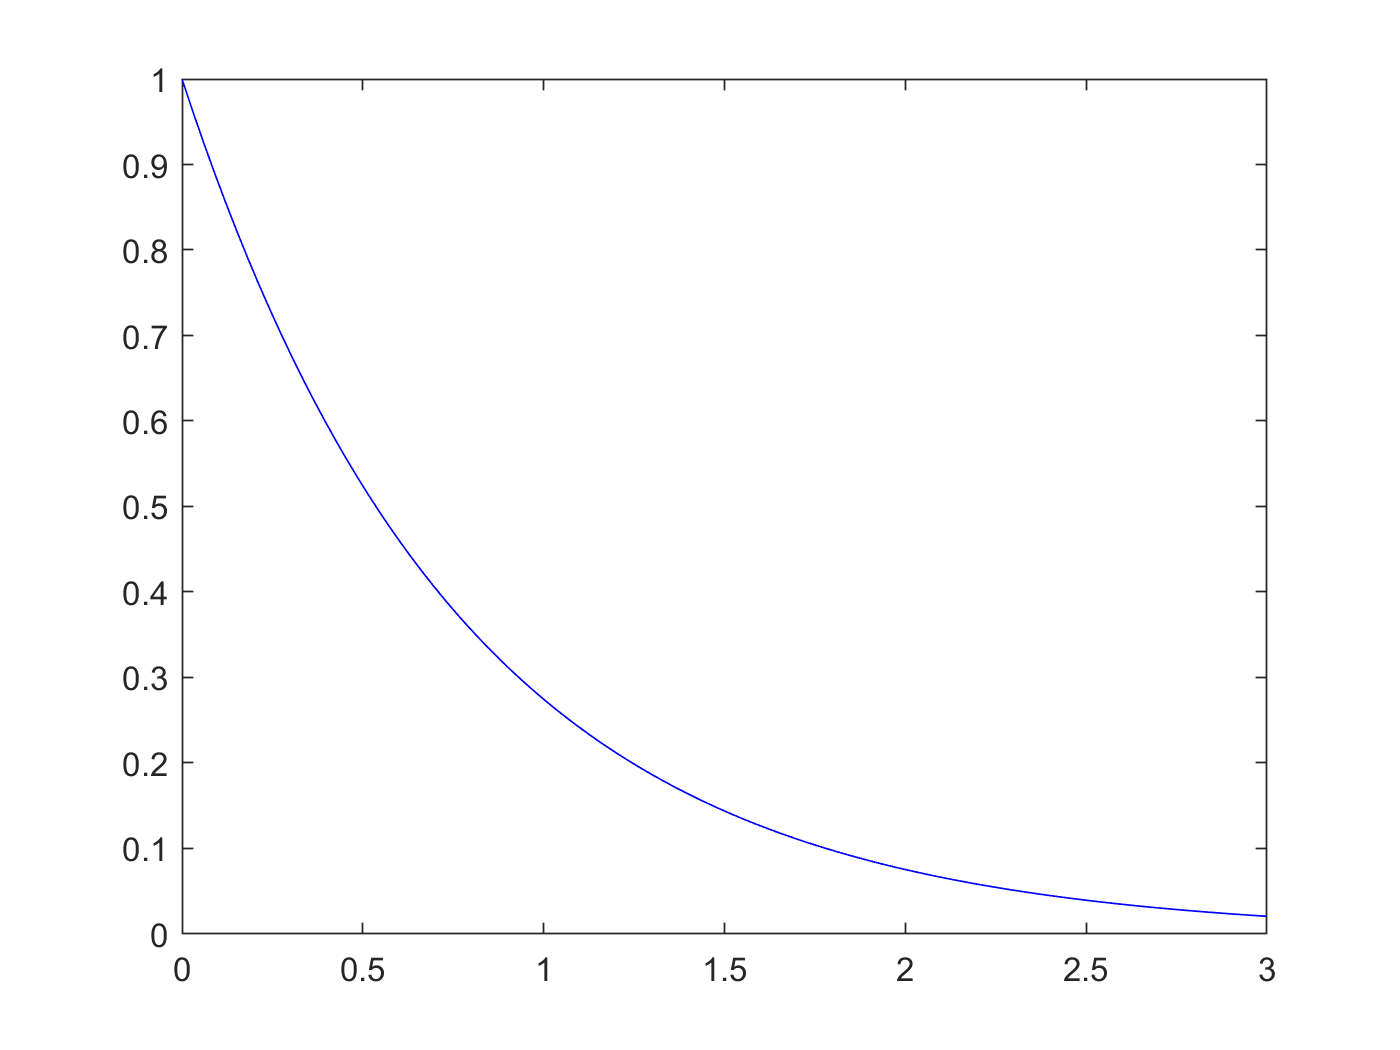

plot(t,predicted,'b-')

function F = myfun(x,c1)
rng default
t = linspace(0,3);
F = exp(-t*x(1)) - (exp(-1.3*t) + c1*randn(size(t)));
end